%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Authors      :-  Manas Kumar Mishra, Niranjana Vannadil 
% Project name :-  SEA (Statistical Enhancement of Audio)
% Organization :-  IIITDM Kancheepuram
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Noisy clips
% 1. TempleNoisyclip1_Agra.mp3
% 2. TempleNoisyclip2_Agra.mp3
% 3. TempleNoisyclip1_Agra.wav
% 4. TempleNoisyclip2_Agra.wav
% 5. TestAudio4.wav

[samples, fsample] = audioread('TestSongs/TestAudio4.wav');

% player = audioplayer(samples, fsample);
% play(player);

fsample %sampling frequency of audio 

fsample = 44100

samples; %Samples, right and left channel

% PSD Show

ShowPSD(samples, fsample);



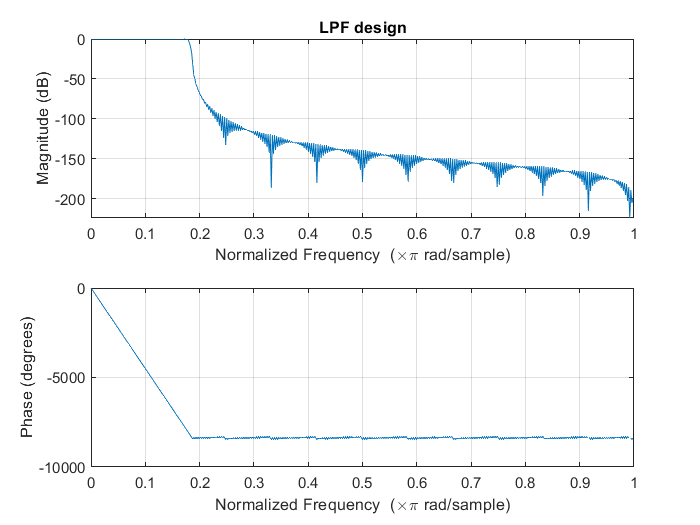

% Preprocessing step
Cutoff = 0.182;

filterLength =500;

filterCoff = impulseResponseOfFilterLPF(Cutoff, filterLength, 3);

NewSamples1 = myFIRFilter(samples(:, 1)', filterCoff);
NewSamples2 = myFIRFilter(samples(:, 2)', filterCoff);
NewSample = [NewSamples1', NewSamples2'];




% player = audioplayer(NewSample, fsample);
% play(player);


% PSD view
ShowPSD(NewSample, fsample);


% Output = MMSESTSA84(NewSample, fsample);

% player = audioplayer(Output, fsample);
% play(player);


a= rand(1, 44100)

a =     0.6648    0.0218    0.3042    0.1237    0.5880    0.6135    0.7908    0.7116    0.9415    0.4820    0.5445    0.4696    0.6877    0.1673    0.2902    0.5660    0.4006    0.1112    0.8491    0.4776    0.3835    0.2177    0.5753    0.4705    0.5057    0.5075    0.3235    0.1122    0.3144    0.0659    0.1386    0.2540    0.1460    0.8845    0.1141    0.9322    0.8407    0.4622    0.1920    0.2522    0.8205    0.4203    0.2941    0.8826    0.8690    0.8178    0.0429    0.6837    0.8350    0.2619



W= ceil(0.032*44100)

W = 1412

Window = hamming(W);
overlappPerc=0.75;
sp = 1-overlappPerc

sp = 0.2500


Window=Window(:);
% a1= NewSample(:, 1)';
L=length(a);

SP=fix(W.*sp);

N=fix((L-W)/SP +1); %number of segments

repmat(1:W, N, 1);
repmat((0:(N-1))'*SP,1,W);
Index=(repmat(1:W,N,1)+repmat((0:(N-1))'*SP,1,W))'

Index =            1         354         707        1060        1413        1766        2119        2472        2825        3178        3531        3884        4237        4590        4943        5296        5649        6002        6355        6708        7061        7414        7767        8120        8473        8826        9179        9532        9885       10238       10591       10944       11297       11650       12003       12356       12709       13062       13415       13768       14121       14474       14827       15180       15533       15886       16239       16592       16945       17298
           2         355         708        1061        1414        1767        2120        2473        2826        3179        3532        3885        4238        4591        4944        5297        5650        6003        6356        6709        7062        7415        7768        8121        8474        8827        9180        9533        9886       10239       10592       10945       

hw=repmat(Window,1,N);
Seg=a(Index);
Seg=a(Index).*hw;

Seg

Seg =     0.0532    0.0331    0.0741    0.0068    0.0088    0.0536    0.0412    0.0790    0.0790    0.0793    0.0329    0.0768    0.0196    0.0679    0.0349    0.0798    0.0201    0.0102    0.0330    0.0750    0.0100    0.0016    0.0242    0.0068    0.0428    0.0432    0.0262    0.0482    0.0038    0.0380    0.0040    0.0232    0.0035    0.0469    0.0759    0.0588    0.0359    0.0368    0.0089    0.0662    0.0278    0.0462    0.0311    0.0088    0.0546    0.0401    0.0160    0.0572    0.0162    0.0053
    0.0017    0.0190    0.0512    0.0163    0.0613    0.0112    0.0405    0.0142    0.0345    0.0131    0.0183    0.0343    0.0074    0.0652    0.0358    0.0391    0.0200    0.0654    0.0595    0.0717    0.0714    0.0097    0.0653    0.0198    0.0663    0.0419    0.0124    0.0682    0.0017    0.0216    0.0640    0.0704    0.0315    0.0090    0.0305    0.0470    0.0417    0.0306    0.0256    0.0278    0.0545    0.0230    0.0766    0.0440    0.0779    0.0484    0.0179    0.0569    0.0718   

% Framing of the sample values
conSampleLength = 0.032

conSampleLength = 0.0320

WinLen = ceil(conSampleLength*fsample);
overlappPerc = 0.75;

[frame1, frame2]= Framing(NewSample,WinLen, overlappPerc, 1);
[FrameSize, NumOfFrame]=size(frame1)

FrameSize = 1412

NumOfFrame = 5980


% Fourier transform of the framed part
FSAMPLE1 = fft(frame1);
FSAMPLE2 = fft(frame2);



% F = FSAMPLE1(1:fix(end), :);

% Experiment 
A = [1, 2, 3, 4;
    2, 4, 5, 6;
    7, 8, 9, 10;
    11, 12, 13, 14];

F = A(1:fix(end))

F =      1     2     7    11     2     4     8    12     3     5     9    13     4     6    10    14


% Convert Matrix into row vector 
F1 = FSAMPLE1(1:fix(end));
F2 = FSAMPLE2(1:fix(end));


% Magnitude term of fft term
F1_mag = abs(F1);
F2_mag = abs(F2);

% Phase term of the signal
F1_phase = angle(F1);
F2_phase = angle(F2);


% Asumming lambda_d (noise  variance) as constant value
Lambda = 0.9;

Alpha = 0.98;
% AlphaVec = Alpha*ones(1, FrameSize)
start =1;
stop = FrameSize;

GammaFunction = gamma(1.5);

Gain = ones(1, FrameSize);
Gamma = Gain;

CleanedAudio1 = zeros(size(F1_mag));
CleanedAudio2 = zeros(size(F2_mag));
h=waitbar(0,'Wait...');

for i = 1:NumOfFrame
    % Something
    
    gammaNew1 = (F1_mag(start:stop).^2)./Lambda;
    
    kssai =Alpha*(Gain.^2).*Gamma+(1-Alpha).*max(gammaNew1, 0) ;
    Gamma = gammaNew1;
    
    nu = Gamma.*kssai/(1+kssai);
    
    Gain = ((GammaFunction*sqrt(nu))./Gamma).*exp(-nu/2).*[(1+nu).*besseli(0, nu/2)+nu.*besseli(1, nu/2)];
    
    Indx=find(isnan(Gain) | isinf(Gain));
    
    Gain(Indx)=kssai(Indx)./(1+kssai(Indx));
    
    CleanedAudio1(start:stop)=Gain.*F1_mag(start:stop);
    CleanedAudio2(start:stop)=Gain.*F2_mag(start:stop);
    
    start = start+FrameSize;
    stop  = stop+FrameSize;
    
    waitbar(i/NumOfFrame,h,num2str(fix(100*i/NumOfFrame)));
end
close(h);


Test1 = rand(10)

Test1 =     0.8816    0.7233    0.5882    0.6237    0.5835    0.8946    0.3876    0.0746    0.9236    0.1999
    0.2707    0.3997    0.8663    0.4794    0.5996    0.7314    0.6683    0.3126    0.0648    0.8618
    0.2893    0.3207    0.6699    0.8270    0.4628    0.2504    0.1629    0.5883    0.1974    0.5063
    0.6457    0.6066    0.3144    0.7317    0.9239    0.8535    0.8427    0.9445    0.9495    0.3001
    0.0298    0.0547    0.9569    0.2263    0.0035    0.8077    0.9773    0.5010    0.3743    0.6237
    0.1873    0.8525    0.9193    0.2048    0.0062    0.2957    0.6387    0.6387    0.0184    0.7534
    0.9730    0.8970    0.9220    0.0001    0.4130    0.5704    0.4677    0.2367    0.2493    0.1345
    0.0300    0.5204    0.5880    0.5315    0.7273    0.2941    0.4792    0.1617    0.0434    0.4959
    0.7923    0.1808    0.1783    0.3176    0.8680    0.3705    0.8279    0.1228    0.1348    0.2514
    0.4356    0.4124    0.3364    0.7555    0.7168    0.2129    0.8783    0.2612   

test2 = zeros(10)

test2 =      0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0



Recon = OverlapAdd2(Test1, test2, FrameSize, ceil(0.25*FrameSize))

Recon =     0.0055
    0.0055
    0.0055
    0.0054
    0.0054
    0.0054
    0.0053
    0.0053
    0.0052
    0.0051
